% Load IBS data
load('D:\data\VALIDEIT09\eit\MIK_P_O\eitV2.mat');
crs = NonInvEIT(eit);

imgFilt = applyFilter(crs,crs.ImgRaw,crs.Fs,false);
imgFilt(isnan(imgFilt)) = 0;

load('D:\data\VALIDEIT09\eit\cct.mat');

t = crs.T;

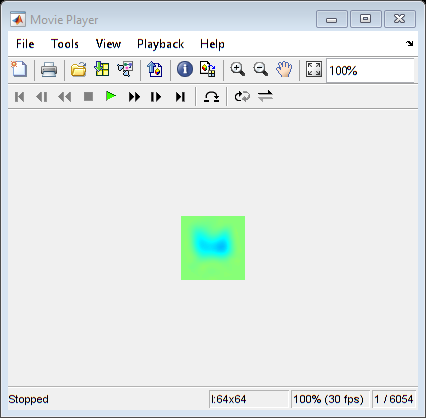

playVideo(imgFilt);

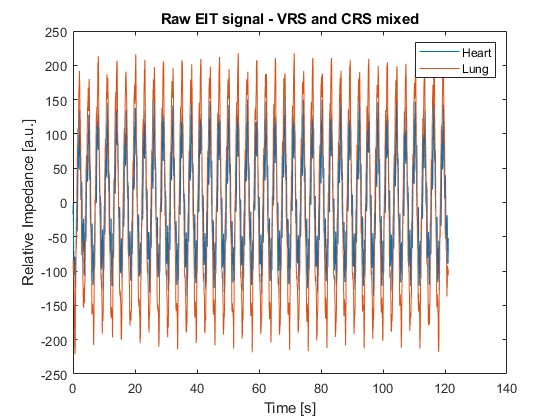

heartPix = [16,30];
lungPix = [30,40];

heartSig = squeeze(imgFilt(heartPix(1),heartPix(2),:));
lungSig = squeeze(imgFilt(lungPix(1),lungPix(2),:));

figure; plot(t, [heartSig,lungSig]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart","Lung"]);
title("Raw EIT signal - VRS and CRS mixed");

[~,mask] = spatialDenoise(imgFilt); mask(isnan(mask)) = 0;
flatIdx = find(mask);
[idxX,idxY] = ind2sub([size(mask,1),size(mask,2)],flatIdx);
imgIdx = [idxX,idxY];

% Initialize DMD class and properties
dmd = DMD();
rank = -1;
halfLife = 0.5;
rho = 2 ^ (- 1 / (halfLife * crs.Fs));
del = 100; % ms
nDel = floor(del * crs.Fs / 1000);

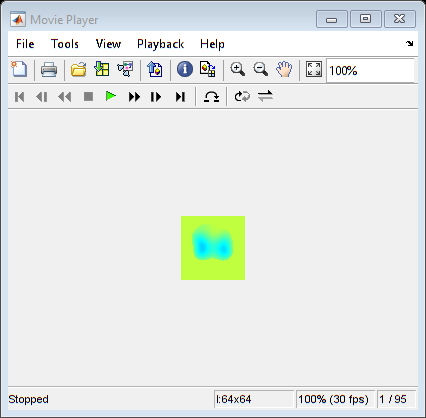

ans =   UnifiedScope with properties:

    InstanceNumber: 12
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]


% INITIALIZATION
wInit = 2; % s
tStart = 0; nStartInit = floor(tStart * crs.Fs + 1);
tEnd = wInit + tStart; nEndInit = ceil(tEnd * crs.Fs);

data = imgFilt(:,:,nStartInit:nEndInit);
flatImg = reshape(data,size(data,1) * size(data,2), []);

predHor = size(data,3)+1;

% X = flatImg(flatIdx,1:end-1);
% Y = flatImg(flatIdx,2:end);

X = hankelTransform(dmd,flatImg(flatIdx,1:end-1), nDel);
Y = hankelTransform(dmd,flatImg(flatIdx,2:end), nDel);

fitKoopman(dmd, X, Y, rank, predHor, 'stream');
fitModes(dmd, X, Y, crs.Fs, 'vanilla');

[Xcomps, Xtotal] = reconData(dmd, [X,Y(:,end)], 'stream');
cleanModes(dmd);
interpModes(dmd);

flatImgRecon = zeros(size(flatImg,1),size(Xtotal,2));
flatImgRecon(flatIdx,:,:) = Xtotal(1:length(flatIdx),:);
XtotalImg = reshape(real(flatImgRecon),64,64,[]);

playVideo(XtotalImg)

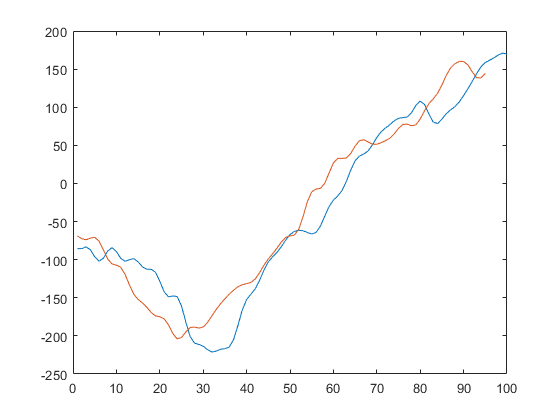

lung = squeeze(data(lungPix(1),lungPix(2),:));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon])

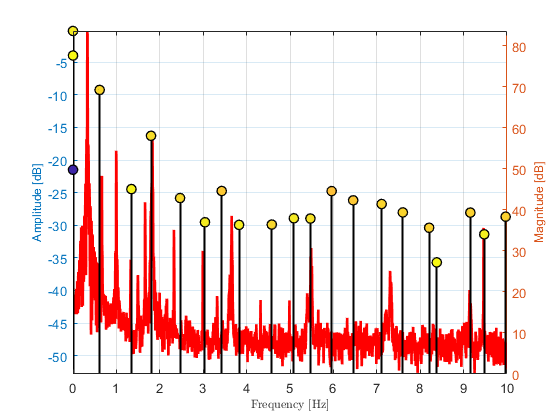

% Corrected frequency plot
powSpect(dmd, reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), [])', crs.Fs);

% Test one update
%% CREATE WINDOWS
w = 1; % s 
nW = floor(w * crs.Fs);

predHor = nW + 1;

flatImg = reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), []);

nStart = nEndInit - nW + 1; 
nEnd = size(imgFilt,3) - nW;

windows = applyWindow(flatImg(flatIdx,:),nStart,nEnd,nW);

%% SLIDING WINDOW
Xfinal = zeros(size(flatImg,1),nW - nDel + 1);

Xnew = hankelTransform(dmd,windows(:,:,1), nDel);
Ynew = hankelTransform(dmd,windows(:,:,2), nDel);

tic
% updateStream(dmd, Xnew, Ynew, rho);
fitKoopman(dmd, Xnew, Ynew, rank, predHor, 'stream');
toc

Elapsed time is 0.027992 seconds.


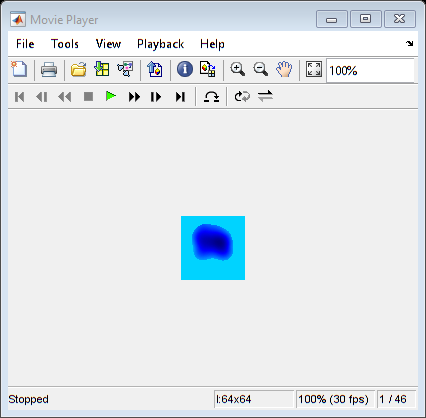


fitModes(dmd, Xnew, Ynew, crs.Fs, 'vanilla');
[~, Xtotal] = reconData(dmd, [Xnew,Ynew(:,end)], 'stream'); 

Xfinal(flatIdx,:) = Xtotal(1:length(flatIdx),:);

XtotalImg = reshape(real(Xfinal),64,64,[]);
playVideo(XtotalImg);

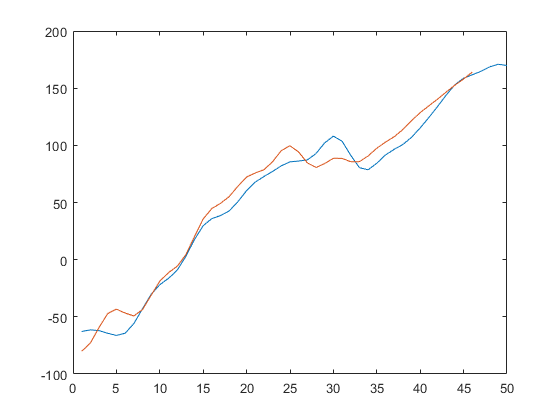

lung = squeeze(imgFilt(lungPix(1),lungPix(2),nStart:nStart+nW - 1));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot([lung]); hold on; plot([lungRecon])

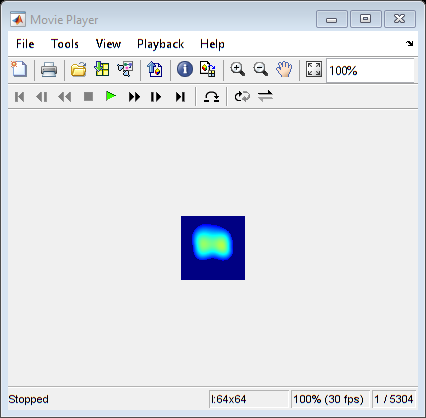

%%% FULL WORKFLOW

%% INITIALIZE DMD CLASS AND PROPERTIES
dmd = DMD();
rank = -1;
halfLife = 5;
rho = 2 ^ (- 1 / (halfLife * crs.Fs));
del = 100; % ms
nDel = floor(del * crs.Fs / 1000);

%5 INITIALIZATION OF ONLINE DMD
wInit = 5; % s
tStart = 10; nStartInit = floor(tStart * crs.Fs + 1);
tEnd = wInit + tStart; nEndInit = ceil(tEnd * crs.Fs);

data = imgFilt(:,:,nStartInit:nEndInit);
flatImg = reshape(data,size(data,1) * size(data,2), []);

predHor = size(data,3)+1;

X = hankelTransform(dmd,flatImg(flatIdx,1:end-1), nDel);
Y = hankelTransform(dmd,flatImg(flatIdx,2:end), nDel);

fitKoopman(dmd, X, Y, rank, predHor, 'stream');
fitModes(dmd, X, Y, crs.Fs, 'vanilla');

%% CREATE WINDOWS
w = 1; % s 
nW = floor(w * crs.Fs);

flatImg = reshape(imgFilt,size(imgFilt,1) * size(imgFilt,2), []);

nStart = nEndInit - nW + 1; 
nEnd = size(imgFilt,3) - nW;

windows = applyWindow(flatImg(flatIdx,:,:),nStart,nEnd,nW);

%% SLIDING WINDOW
Xfinal = zeros(size(flatImg,1),size(windows,3));
compTime = zeros(size(windows,3),1);
for i = 1:500 % size(windows,3)
    Xnew = hankelTransform(dmd,windows(:,:,i), nDel);
    Ynew = hankelTransform(dmd,windows(:,:,i + 1), nDel);
    
    tic
    updateStream(dmd, Xnew, Ynew, rho);
    compTime(i) = toc;
    
    fitModes(dmd, X, Y, crs.Fs, 'vanilla');
    [~, Xtotal] = reconData(dmd, nW); 
    
    Xfinal(flatIdx,i) = Xtotal(1:length(flatIdx));
end

XtotalImg = reshape(real(Xfinal),64,64,[]);
playVideo(XtotalImg);

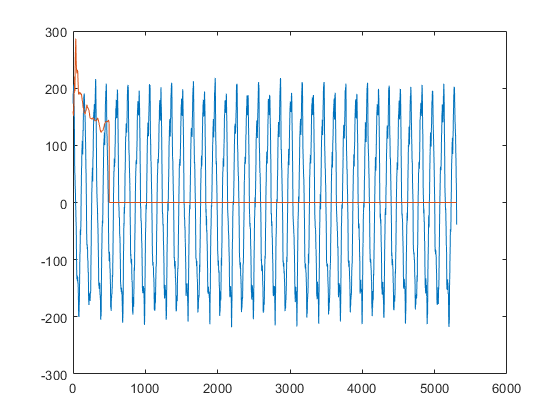

lung = squeeze(imgFilt(lungPix(1),lungPix(2),nStart:nEnd));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot([lung, lungRecon])

function x = applyWindow(y,nStart,nEnd,nW)
    x = zeros(size(y,1),nW,nEnd - nStart);
    wCount = 1;
    for i = nStart:nEnd
        x(:,:,wCount) = y(:,i:i + nW - 1);
        wCount = wCount + 1;
    end
end